%% 最终合并图：POC热浪/非热浪空间分布 + 年际（折线+柱状） + 四季热浪期变化（线加粗）
fprintf('绘制POC合并图（四个子图）...\n');

绘制POC合并图（四个子图）...


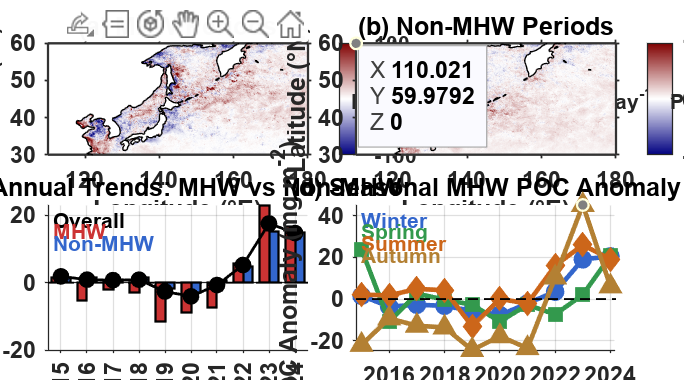


% 确保 lon_range, lat_range 存在
if ~exist('lon_range', 'var')
    lon_range = [110, 180];
    lat_range = [30, 60];
end

% ========== 1. 年际数据（包含2024年） ==========
if exist('annual_hw_anomaly', 'var') && exist('annual_non_hw_anomaly', 'var') && exist('unique_years', 'var')
    years_bar = unique_years;
    annual_hw_bar = annual_hw_anomaly;
    annual_non_hw_bar = annual_non_hw_anomaly;
    if exist('annual_overall_anomaly', 'var')
        annual_overall_bar = annual_overall_anomaly;
    else
        annual_overall_bar = (annual_hw_bar + annual_non_hw_bar) / 2;
    end
else
    error('年际数据变量不存在，请检查工作区');
end

% ========== 2. 四季热浪期数据（保留2024年，线条加粗） ==========
if exist('seasonal_ts_hw', 'var')
    years_season = seasonal_ts_hw.years;
    winter_hw = seasonal_ts_hw.winter;
    spring_hw = seasonal_ts_hw.spring;
    summer_hw = seasonal_ts_hw.summer;
    autumn_hw = seasonal_ts_hw.autumn;
else
    error('seasonal_ts_hw 变量不存在，请检查工作区');
end

% ========== 3. 创建图形 ==========
fig = figure('Position', [100, 100, 1450, 950], 'Color', 'white');
ax_fontsize = 10;
legend_fontsize = 9;
title_fontsize = 11;
linewidth = 1.2;
linewidth_season = 2.0;  % d图加粗线条

% ---------- 子图1 (a)：热浪期POC异常 ----------
ax1 = subplot(2,2,1);
h1 = pcolor(LON, LAT, mean_hw_anom);
set(h1, 'EdgeColor', 'none');
colormap(ax1, redblue_cmap);
caxis([-100, 100]);
xlabel('Longitude (°E)', 'FontSize', ax_fontsize, 'FontWeight', 'bold');
ylabel('Latitude (°N)', 'FontSize', ax_fontsize, 'FontWeight', 'bold');
title('(a) MHW Periods', 'FontSize', title_fontsize, 'FontWeight', 'bold');
hold on;
plot([lon_range(1) lon_range(2) lon_range(2) lon_range(1) lon_range(1)], ...
     [lat_range(1) lat_range(1) lat_range(2) lat_range(2) lat_range(1)], ...
     'k-', 'LineWidth', 1, 'Color', [0.2 0.2 0.2]);
try
    if exist('coastlines.mat', 'file')
        load coastlines;
        coastlon_clean = coastlon;
        coastlat_clean = coastlat;
        dx = [0; diff(coastlon)];
        dy = [0; diff(coastlat)];
        large_jumps = (abs(dx) > 10) | (abs(dy) > 10);
        coastlon_clean(large_jumps) = NaN;
        coastlat_clean(large_jumps) = NaN;
        plot(coastlon_clean, coastlat_clean, 'k-', 'LineWidth', 0.6);
    end
end
axis equal;
xlim(lon_range);
ylim(lat_range);
set(gca, 'TickDir', 'out', 'LineWidth', 0.8, 'FontSize', ax_fontsize, ...
         'FontWeight', 'bold', 'Color', 'white');
cb1 = colorbar('Location', 'eastoutside');
cb1.Label.String = 'POC Anomaly (mg C m^{-2} day^{-1})';
cb1.Label.FontSize = ax_fontsize-1;
cb1.Label.FontWeight = 'bold';
cb1.Label.Rotation = 0;
drawnow;
cb1.Label.VerticalAlignment = 'middle';
cb1.Label.HorizontalAlignment = 'left';
cb_pos = get(cb1, 'Position');
set(cb1.Label, 'Position', [cb_pos(1)+cb_pos(3)+0.005, cb_pos(2)+cb_pos(4)/2, 0]);
cb1.FontSize = ax_fontsize-1;
cb1.FontWeight = 'bold';

% ---------- 子图2 (b)：非热浪期POC异常 ----------
ax2 = subplot(2,2,2);
h2 = pcolor(LON, LAT, mean_non_hw_anom);
set(h2, 'EdgeColor', 'none');
colormap(ax2, redblue_cmap);
caxis([-100, 100]);
xlabel('Longitude (°E)', 'FontSize', ax_fontsize, 'FontWeight', 'bold');
ylabel('Latitude (°N)', 'FontSize', ax_fontsize, 'FontWeight', 'bold');
title('(b) Non-MHW Periods', 'FontSize', title_fontsize, 'FontWeight', 'bold');
hold on;
plot([lon_range(1) lon_range(2) lon_range(2) lon_range(1) lon_range(1)], ...
     [lat_range(1) lat_range(1) lat_range(2) lat_range(2) lat_range(1)], ...
     'k-', 'LineWidth', 1, 'Color', [0.2 0.2 0.2]);
try
    if exist('coastlines.mat', 'file')
        load coastlines;
        coastlon_clean = coastlon;
        coastlat_clean = coastlat;
        dx = [0; diff(coastlon)];
        dy = [0; diff(coastlat)];
        large_jumps = (abs(dx) > 10) | (abs(dy) > 10);
        coastlon_clean(large_jumps) = NaN;
        coastlat_clean(large_jumps) = NaN;
        plot(coastlon_clean, coastlat_clean, 'k-', 'LineWidth', 0.6);
    end
end
axis equal;
xlim(lon_range);
ylim(lat_range);
set(gca, 'TickDir', 'out', 'LineWidth', 0.8, 'FontSize', ax_fontsize, ...
         'FontWeight', 'bold', 'Color', 'white');
cb2 = colorbar('Location', 'eastoutside');
cb2.Label.String = 'POC Anomaly (mg C m^{-2} day^{-1})';
cb2.Label.FontSize = ax_fontsize-1;
cb2.Label.FontWeight = 'bold';
cb2.Label.Rotation = 0;
drawnow;
cb2.Label.VerticalAlignment = 'middle';
cb2.Label.HorizontalAlignment = 'left';
cb_pos = get(cb2, 'Position');
set(cb2.Label, 'Position', [cb_pos(1)+cb_pos(3)+0.005, cb_pos(2)+cb_pos(4)/2, 0]);
cb2.FontSize = ax_fontsize-1;
cb2.FontWeight = 'bold';

% ---------- 子图3 (c)：年际变化（总体折线 + 热浪/非热浪柱状图，含2024） ----------
ax3 = subplot(2,2,3);
hold on;
bar_width = 0.35;
x_pos = 1:length(years_bar);
% 热浪期柱（红色）
b1 = bar(x_pos - bar_width/2, annual_hw_bar, bar_width, 'FaceColor', [0.8 0.2 0.2], 'EdgeColor', 'k', 'LineWidth', 1);
% 非热浪期柱（蓝色）
b2 = bar(x_pos + bar_width/2, annual_non_hw_bar, bar_width, 'FaceColor', [0.2 0.4 0.8], 'EdgeColor', 'k', 'LineWidth', 1);
% 总体平均折线（黑色）
plot(x_pos, annual_overall_bar, 'ko-', 'LineWidth', linewidth, 'MarkerSize', 6, 'MarkerFaceColor', 'k');
% 零线
plot([0.5, length(years_bar)+0.5], [0,0], 'k--', 'LineWidth', 0.8);
xlabel('Year', 'FontSize', ax_fontsize, 'FontWeight', 'bold');
ylabel('POC Anomaly (mg m^{-2} )', 'FontSize', ax_fontsize, 'FontWeight', 'bold');
title('(c) Annual Trends: MHW vs Non-MHW', 'FontSize', title_fontsize, 'FontWeight', 'bold');
set(gca, 'XTick', x_pos, 'XTickLabel', years_bar, 'FontSize', ax_fontsize, ...
         'FontWeight', 'bold', 'TickDir', 'out');
xlim([0.5, length(years_bar)+0.5]);
grid on;
% 文本图例
text(0.02, 0.98, 'Overall', 'Units', 'normalized', 'VerticalAlignment', 'top', ...
     'Color', 'k', 'FontSize', legend_fontsize, 'FontWeight', 'bold');
text(0.02, 0.90, 'MHW', 'Units', 'normalized', 'VerticalAlignment', 'top', ...
     'Color', [0.8 0.2 0.2], 'FontSize', legend_fontsize, 'FontWeight', 'bold');
text(0.02, 0.82, 'Non-MHW', 'Units', 'normalized', 'VerticalAlignment', 'top', ...
     'Color', [0.2 0.4 0.8], 'FontSize', legend_fontsize, 'FontWeight', 'bold');

% ---------- 子图4 (d)：四季热浪期异常（线条加粗，保留2024） ----------
ax4 = subplot(2,2,4);
hold on;
season_colors = [0.2 0.4 0.8;   % 冬季 - 蓝
                 0.2 0.6 0.3;   % 春季 - 绿
                 0.8 0.4 0.1;   % 夏季 - 橙
                 0.7 0.5 0.2];  % 秋季 - 棕
plot(years_season, winter_hw, '-o', 'Color', season_colors(1,:), 'LineWidth', linewidth_season, ...
     'MarkerSize', 6, 'MarkerFaceColor', season_colors(1,:));
plot(years_season, spring_hw, '-s', 'Color', season_colors(2,:), 'LineWidth', linewidth_season, ...
     'MarkerSize', 6, 'MarkerFaceColor', season_colors(2,:));
plot(years_season, summer_hw, '-d', 'Color', season_colors(3,:), 'LineWidth', linewidth_season, ...
     'MarkerSize', 6, 'MarkerFaceColor', season_colors(3,:));
plot(years_season, autumn_hw, '-^', 'Color', season_colors(4,:), 'LineWidth', linewidth_season, ...
     'MarkerSize', 6, 'MarkerFaceColor', season_colors(4,:));
plot([min(years_season)-0.5, max(years_season)+0.5], [0,0], 'k--', 'LineWidth', 0.8);
xlabel('Year', 'FontSize', ax_fontsize, 'FontWeight', 'bold');
ylabel('POC Anomaly (mg m^{-2})', 'FontSize', ax_fontsize, 'FontWeight', 'bold');
title('(d) Seasonal MHW POC Anomaly', 'FontSize', title_fontsize, 'FontWeight', 'bold');
grid on;
set(gca, 'FontSize', ax_fontsize, 'FontWeight', 'bold', 'TickDir', 'out');
xlim([min(years_season)-0.2, max(years_season)+0.2]);
% 文本图例
text(0.02, 0.98, 'Winter', 'Units', 'normalized', 'VerticalAlignment', 'top', ...
     'Color', season_colors(1,:), 'FontSize', legend_fontsize, 'FontWeight', 'bold');
text(0.02, 0.90, 'Spring', 'Units', 'normalized', 'VerticalAlignment', 'top', ...
     'Color', season_colors(2,:), 'FontSize', legend_fontsize, 'FontWeight', 'bold');
text(0.02, 0.82, 'Summer', 'Units', 'normalized', 'VerticalAlignment', 'top', ...
     'Color', season_colors(3,:), 'FontSize', legend_fontsize, 'FontWeight', 'bold');
text(0.02, 0.74, 'Autumn', 'Units', 'normalized', 'VerticalAlignment', 'top', ...
     'Color', season_colors(4,:), 'FontSize', legend_fontsize, 'FontWeight', 'bold');

% 调整子图位置
set(ax1, 'Position', [0.07, 0.55, 0.38, 0.38]);
set(ax2, 'Position', [0.52, 0.55, 0.38, 0.38]);
set(ax3, 'Position', [0.07, 0.08, 0.38, 0.38]);
set(ax4, 'Position', [0.52, 0.08, 0.38, 0.38]);

% 保存图形
saveas(fig, fullfile(output_dir, 'POC_Combined_Four_Panels.png'));
print(fig, fullfile(output_dir, 'POC_Combined_Four_Panels.png'), '-dpng', '-r300');

fprintf('POC合并图已保存：POC_Combined_Four_Panels.png\n');

POC合并图已保存：POC_Combined_Four_Panels.png
